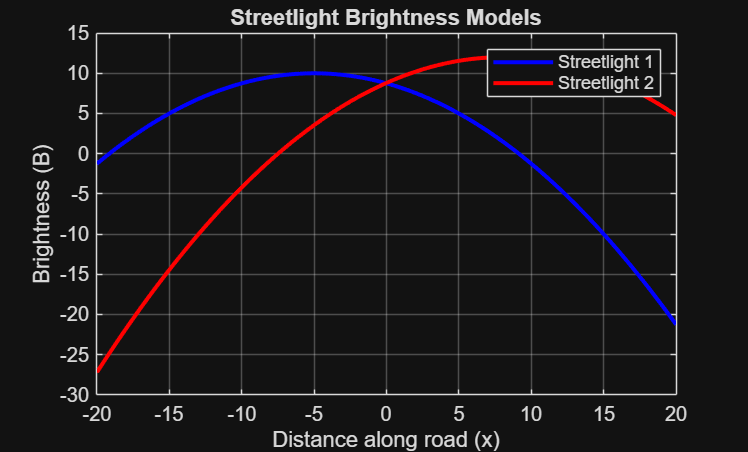

%{
streetlight brightness model (quadratic + shifts)
Author: Diem-Linh Phan
Date: 4-30-2026
Purpose:
    Models streetlight brightness
Input:
    - N/A: Function is not expecting arguments.
Output:
    - Graph showing streetlight brightness models 
MATLAB tools/functions:
    - functions
    - plots
%}
% Define the range for x
x = -20:0.5:20;

% Define brightness models
B1 = -0.05*(x + 5).^2 + 10;
B2 = -0.05*(x - 8).^2 + 12;

% Task 3: Plotting
figure;
plot(x, B1, 'b', 'LineWidth', 2); hold on;
plot(x, B2, 'r', 'LineWidth', 2);
grid on;
xlabel('Distance along road (x)');
ylabel('Brightness (B)');
legend('Streetlight 1', 'Streetlight 2');
title('Streetlight Brightness Models');


% Task 4: Identify Maxima
[maxB1, idx1] = max(B1);
[maxB2, idx2] = max(B2);
fprintf('Streetlight 1 max is %.1f at x = %.1f\n', maxB1, x(idx1));

Streetlight 1 max is 10.0 at x = -5.0


fprintf('Streetlight 2 max is %.1f at x = %.1f\n', maxB2, x(idx2));

Streetlight 2 max is 12.0 at x = 8.0



% Task 5: Approximate Intersection
[~, intersectIdx] = min(abs(B1 - B2));
fprintf('The curves intersect approximately at x = %.1f\n', x(intersectIdx));

The curves intersect approximately at x = 0.0


%{

%}
